# How to Solve for the Equations of Motion Using MATLAB

Note:  This script was generated with MATLAB 2016b - certain features may work differently (or not at all) on earlier releases.  This requires the symbolic math toolbox.

## Problem Setup

We will be solving for the equations of motion of a spring pendulum in the presence of gravity and no other external forces.  The pendulum bob has mass $m$ with arm length given by  $r$. The spring has constant $k$ and rest length $l_0$.  We will use an inertial frame $\mathcal{I} = (O,\mathbf{e}_1,\mathbf{e}_2,\mathbf{e}_3)$ with $\mathbf{e}_1$ pointing in the direction of the gravity force (i.e., downwards) and $O$ being the pendulum's attchment point, and polar frame: $\mathcal{B} = (O,\mathbf{e}_r,\mathbf{e}_\theta, \mathbf{e}_3)$, with $\mathbf{e}_r$ pointing along the direction of the pendulum arm at an angle $\theta$ from $\mathbf{e}_1$(so that when $\theta = 0$, the pendulum is hanging straight down). 

We will look at two different methods of finding these equations of motion - both resulting in the same equations of motion, and both using the same frames and coordinates, but performing the calculations in slightly different ways.

## Method 1: Letting MATLAB do all of the derivatives for us.

This method involves defining some variables as time varying, but then requires us to explicitly subsitute for derivative quantities in later algebraic steps.

First define all of the symbolic variables we will require:

syms m g k l_0 'positive' %we are assuming these are all positive quantities
syms r(t) theta(t) %we are explicitly defining r and theta as functions of time

Now we do the kinematics (all using $\mathcal
 B$ frame components):


$$\mathbf{r}_{P/O} = r \mathbf{e}_r\\
{}^\mathcal{I}\mathbf{\omega}^\mathcal{B} = \dot\theta \mathbf e_3$$


r_PO_B = [r;0;0] %make sure that everything is a column vector (and 3x1)

$$r\_PO\_B(t) = \left(\begin{array}{c} r\left(t\right)\\ 0\\ 0 \end{array}\right)$$

iWb = [0;0;diff(theta,t)]

$$iWb(t) = \left(\begin{array}{c} 0\\ 0\\ \frac{\partial }{\partial t}\theta \left(t\right) \end{array}\right)$$

Now we can apply the transport equation to get velocity and acceleration.  Note that the derivatives that MATLAB is calculating are automatically in the frame in which the components of our vectors were defined (in this case $\mathcal B$):

v_PO_B = diff(r_PO_B,t) + cross(iWb,r_PO_B)

$$v\_PO\_B(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}r\left(t\right)\\ r\left(t\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\\ 0 \end{array}\right)$$

a_PO_B = diff(v_PO_B,t) + cross(iWb,v_PO_B)

$$a\_PO\_B(t) = \left(\begin{array}{c} \frac{\partial^{2}}{\partial t^{2}}r\left(t\right)-r\left(t\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\\ r\left(t\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}r\left(t\right)\,2\\ 0 \end{array}\right)$$

Now we calculate the forces. Remeber:


$$\mathbf F_g = mg \mathbf{e}_1\\ \mathbf{F}_s = -k(r-l_0)\mathbf{e}_r$$


F_g_I = [m*g;0;0]

$$F\_g\_I = \left(\begin{array}{c} g\,m\\ 0\\ 0 \end{array}\right)$$

F_s_B = [-k*(r-l_0);0;0]

$$F\_s\_B(t) = \left(\begin{array}{c} k\,\left(l_{0}-r\left(t\right)\right)\\ 0\\ 0 \end{array}\right)$$

Now, in order to get the gravity force into $\mathcal B$ frame components, we will need a direction cosine matrix (${}^{\mathcal{B}}C^\mathcal{I}$):

bCi = [cos(theta) sin(theta) 0;-sin(theta) cos(theta) 0;0 0 1]

$$bCi(t) = \left(\begin{array}{ccc} \cos\left(\theta \left(t\right)\right) & \sin\left(\theta \left(t\right)\right) & 0\\ -\sin\left(\theta \left(t\right)\right) & \cos\left(\theta \left(t\right)\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

F_g_B = bCi*F_g_I

$$F\_g\_B(t) = \left(\begin{array}{c} g\,m\,\cos\left(\theta \left(t\right)\right)\\ -g\,m\,\sin\left(\theta \left(t\right)\right)\\ 0 \end{array}\right)$$

Now we can set up the vector equations of motion:

eom = m*a_PO_B == F_g_B + F_s_B

$$eom(t) = \left(\begin{array}{c} -m\,\left(r\left(t\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}-\frac{\partial^{2}}{\partial t^{2}}r\left(t\right)\right)=k\,\left(l_{0}-r\left(t\right)\right)+g\,m\,\cos\left(\theta \left(t\right)\right)\\ m\,\left(r\left(t\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}r\left(t\right)\,2\right)=-g\,m\,\sin\left(\theta \left(t\right)\right)\\ 0=0 \end{array}\right)$$

And finally, solve for the second derivatives of our variables.  Note:  as of 2016b, MATLAB cannot handle solving for a function of another variable. This will likely change in subsequent releases. For now, we subsititute dummy variables for the second derivatives:

syms rr th rd thd rdd thdd
scalar_eoms = solve(subs(eom,[diff(r,t,t),diff(theta,t,t)],[rdd,thdd]),[rdd,thdd],'ReturnConditions',true)

scalar_eoms =            rdd: [1×1 sym]
          thdd: [1×1 sym]
    parameters: [1×0 sym]
    conditions: [1×1 sym]


scalar_eoms.rdd, scalar_eoms.thdd

$$ans = \frac{m\,r\left(t\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+k\,l_{0}-k\,r\left(t\right)+g\,m\,\cos\left(\theta \left(t\right)\right)}{m}$$

$$ans = -\frac{\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}r\left(t\right)\,2+g\,\sin\left(\theta \left(t\right)\right)}{r\left(t\right)}$$

At this point, we probably want to numerically integrate, so we turn these solutions into functions.  Again, there are many ways to do this, but we will generate two nested lambda functions, evaluating the state vector derivative direction.  We assume a state vector of the form:


$$z = \left[ r , \dot{r}, \theta, \dot\theta\right]^T$$
 

dz = simplify([rd;subs(scalar_eoms.rdd,[r,theta, diff(r,t), diff(theta,t)], [rr,th,rd,thd]); thd; subs(scalar_eoms.thdd,[r,theta, diff(r,t), diff(theta,t)], [rr,th,rd,thd])])

$$dz = \left(\begin{array}{c} \mathrm{rd}\\ \frac{m\,\mathrm{rr}\,{\mathrm{thd}}^{2}+k\,l_{0}-k\,\mathrm{rr}+g\,m\,\cos\left(\mathrm{th}\right)}{m}\\ \mathrm{thd}\\ -\frac{2\,\mathrm{rd}\,\mathrm{thd}+g\,\sin\left(\mathrm{th}\right)}{\mathrm{rr}} \end{array}\right)$$

f1 = matlabFunction(dz,'vars',{rr,rd,th,thd,g,m,l_0,k})

f1 =     @(rr,rd,th,thd,g,m,l_0,k)[rd;(k.*l_0-k.*rr+g.*m.*cos(th)+m.*rr.*thd.^2)./m;thd;-(rd.*thd.*2.0+g.*sin(th))./rr]


In order to numerically integrate, we need a function that takes in the state vector and time as inputs, so we simply wrap another lambda function about the first one.  Alternatively, we could also write this function out to disk (see matlabFunction documentation for details on that).

f2 = @(t,z) f1(z(1),z(2),z(3),z(4),9.81, 0.1, 0.1, 2)

f2 =     @(t,z)f1(z(1),z(2),z(3),z(4),9.81,0.1,0.1,2)


We can now numerically integrate, with some assumed initial conditions:

[T,Z] = ode45(f2,linspace(0,20,1000),[0.5,0,pi/3,0]);

And finally, we plot:

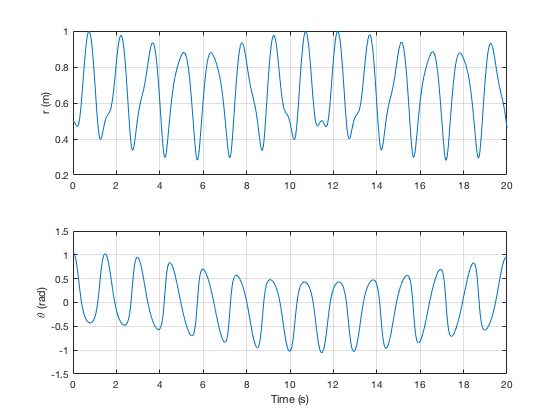

subplot(2,1,1)
plot(T,Z(:,1))
grid on
ylabel('r (m)')
subplot(2,1,2)
plot(T,Z(:,3))
ylabel('\theta (rad)')
xlabel('Time (s)')
grid on

## Method 2 - We do all differentiation ourselves (but then less substitution at the end)

In this case, we will work entirely in the inertial frame to make differentiation more straightforward.  Note that we are redefining multiple variables defined above in different ways. We first define our state variables and a generalized derivative function:

syms m g k l_0 'positive'
syms r th rd thd rdd thdd 'real'
z = [r;rd;th;thd]

$$z = \left(\begin{array}{c} r\\ \mathrm{rd}\\ \mathrm{th}\\ \mathrm{thd} \end{array}\right)$$

dz = [rd;rdd;thd;thdd];
derivative = @(in)( jacobian(in,z)*dz )

derivative =     @(in)(jacobian(in,z)*dz)


We define the kinematics as before, but now convert everything to inertial frame components:

r_PO_B = [r;0;0]

$$r\_PO\_B = \left(\begin{array}{c} r\\ 0\\ 0 \end{array}\right)$$

bCi = [cos(th) sin(th) 0;-sin(th) cos(th) 0;0 0 1]

$$bCi = \left(\begin{array}{ccc} \cos\left(\mathrm{th}\right) & \sin\left(\mathrm{th}\right) & 0\\ -\sin\left(\mathrm{th}\right) & \cos\left(\mathrm{th}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

r_PO_I = transpose(bCi)*r_PO_B

$$r\_PO\_I = \left(\begin{array}{c} r\,\cos\left(\mathrm{th}\right)\\ r\,\sin\left(\mathrm{th}\right)\\ 0 \end{array}\right)$$

v_PO_I = derivative(r_PO_I)

$$v\_PO\_I = \left(\begin{array}{c} \mathrm{rd}\,\cos\left(\mathrm{th}\right)-r\,\mathrm{thd}\,\sin\left(\mathrm{th}\right)\\ \mathrm{rd}\,\sin\left(\mathrm{th}\right)+r\,\mathrm{thd}\,\cos\left(\mathrm{th}\right)\\ 0 \end{array}\right)$$

a_PO_I = derivative(v_PO_I)

$$a\_PO\_I = \left(\begin{array}{c} \mathrm{rdd}\,\cos\left(\mathrm{th}\right)-\mathrm{thd}\,\left(\mathrm{rd}\,\sin\left(\mathrm{th}\right)+r\,\mathrm{thd}\,\cos\left(\mathrm{th}\right)\right)-r\,\mathrm{thdd}\,\sin\left(\mathrm{th}\right)-\mathrm{rd}\,\mathrm{thd}\,\sin\left(\mathrm{th}\right)\\ \mathrm{thd}\,\left(\mathrm{rd}\,\cos\left(\mathrm{th}\right)-r\,\mathrm{thd}\,\sin\left(\mathrm{th}\right)\right)+\mathrm{rdd}\,\sin\left(\mathrm{th}\right)+r\,\mathrm{thdd}\,\cos\left(\mathrm{th}\right)+\mathrm{rd}\,\mathrm{thd}\,\cos\left(\mathrm{th}\right)\\ 0 \end{array}\right)$$

Forces are also the same, except once again we will express them in the inertial frame:

F_g_I = [m*g;0;0]

$$F\_g\_I = \left(\begin{array}{c} g\,m\\ 0\\ 0 \end{array}\right)$$

F_s_B = [-k*(r-l_0);0;0]

$$F\_s\_B = \left(\begin{array}{c} k\,\left(l_{0}-r\right)\\ 0\\ 0 \end{array}\right)$$

F_s_I = transpose(bCi)*F_s_B

$$F\_s\_I = \left(\begin{array}{c} k\,\cos\left(\mathrm{th}\right)\,\left(l_{0}-r\right)\\ k\,\sin\left(\mathrm{th}\right)\,\left(l_{0}-r\right)\\ 0 \end{array}\right)$$

Just for variety, we'll solve this linear system slightly differently from before (although the mechanics are basically exactly the same):

[A,b] = equationsToMatrix(m*a_PO_I - (F_s_I + F_g_I),[rdd,thdd])

$$A = \left(\begin{array}{cc} m\,\cos\left(\mathrm{th}\right) & -m\,r\,\sin\left(\mathrm{th}\right)\\ m\,\sin\left(\mathrm{th}\right) & m\,r\,\cos\left(\mathrm{th}\right)\\ 0 & 0 \end{array}\right)$$

$$b = \left(\begin{array}{c} g\,m+m\,\left(\mathrm{thd}\,\left(\mathrm{rd}\,\sin\left(\mathrm{th}\right)+r\,\mathrm{thd}\,\cos\left(\mathrm{th}\right)\right)+\mathrm{rd}\,\mathrm{thd}\,\sin\left(\mathrm{th}\right)\right)+k\,\cos\left(\mathrm{th}\right)\,\left(l_{0}-r\right)\\ k\,\sin\left(\mathrm{th}\right)\,\left(l_{0}-r\right)-m\,\left(\mathrm{thd}\,\left(\mathrm{rd}\,\cos\left(\mathrm{th}\right)-r\,\mathrm{thd}\,\sin\left(\mathrm{th}\right)\right)+\mathrm{rd}\,\mathrm{thd}\,\cos\left(\mathrm{th}\right)\right)\\ 0 \end{array}\right)$$

soln = simplify(A\b)

$$soln = \left(\begin{array}{c} \frac{m\,r\,{\mathrm{thd}}^{2}+k\,l_{0}-k\,r+g\,m\,\cos\left(\mathrm{th}\right)}{m}\\ -\frac{2\,\mathrm{rd}\,\mathrm{thd}+g\,\sin\left(\mathrm{th}\right)}{r} \end{array}\right)$$

From here, setting up the numerical integration is exactly the same as in Method one.